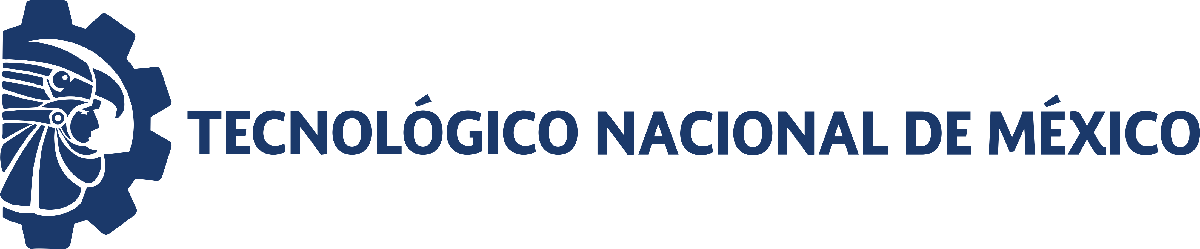                                 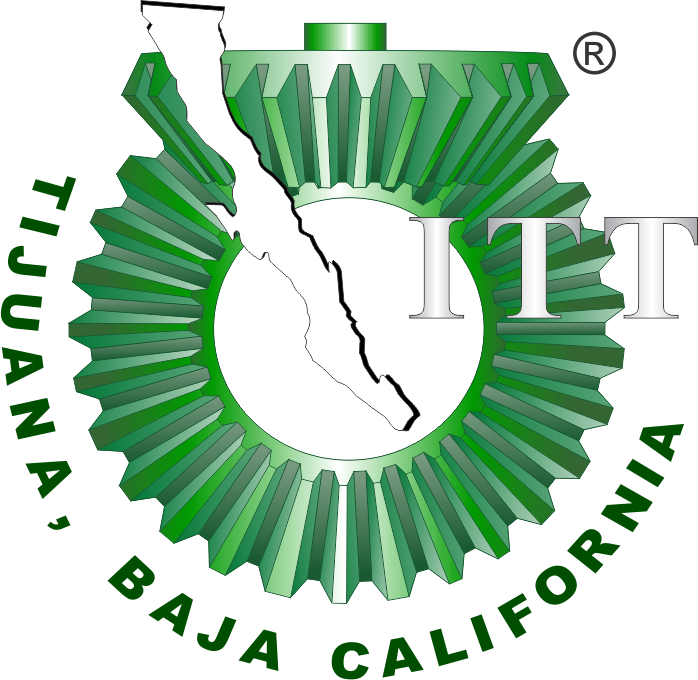

# Práctica dos: Modelado y control del sistema cardiovascular mediante el modelo Windkessel

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

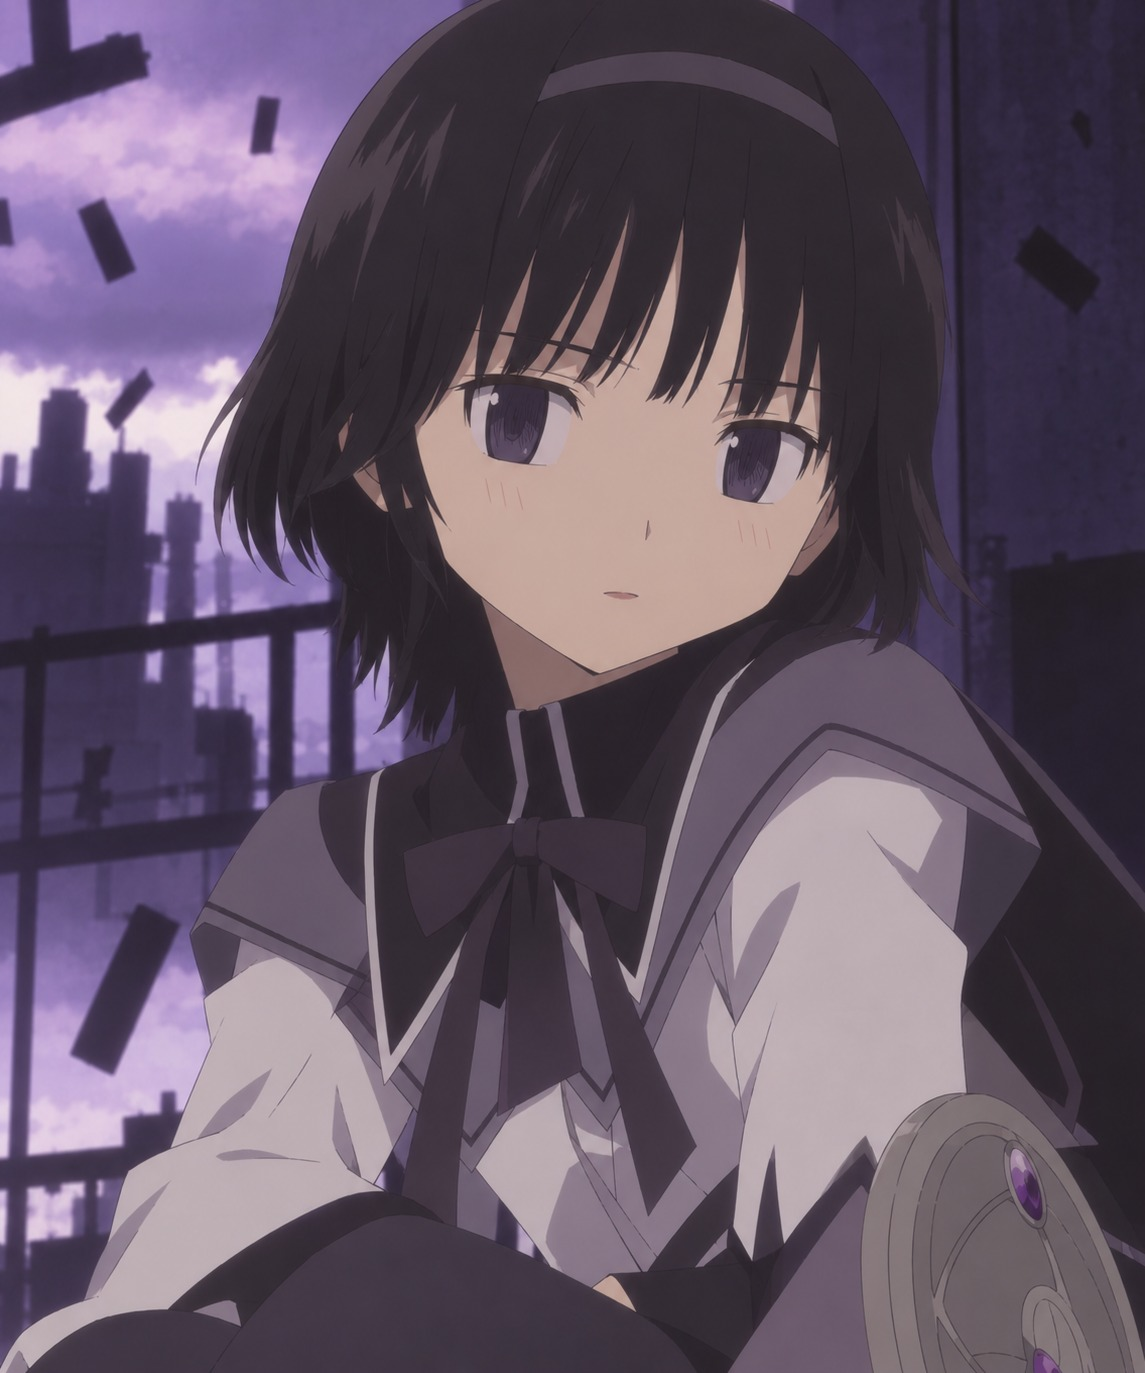

Nombre del alumno: Carolina Gamez Flores

Número de control: 23212193

Correo institucional: l23212193**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x=sim('sistema',parameters);
t_data = (0:0.1:15)';
t=(0:0.001:15)';
Pa=interp1(t_data, x.Pa, t, 'previous');
writematrix(Pa,'signal.xlsx');

% set_param('sistema/Vs(t)','VectorFormat','1-D array')

## Respuesta: Hipotenso, Normotenso, Hipertenso

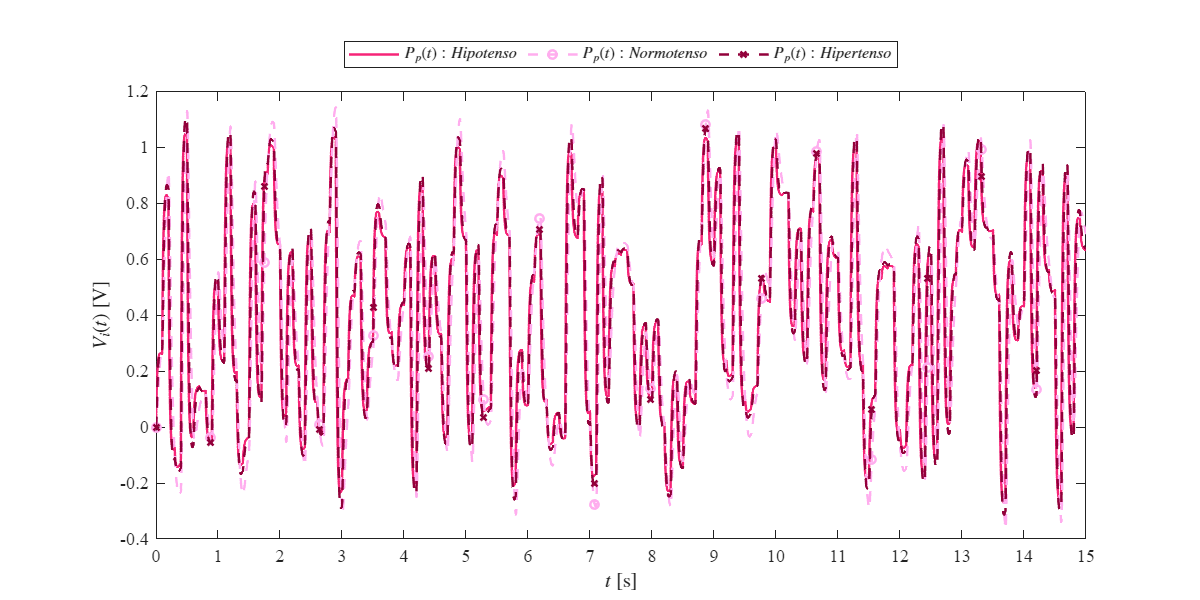

plotsignals(x.t,x.PpN,x.PpL,x.PpH,'Individuos')

## Respuesta: Hipotenso 

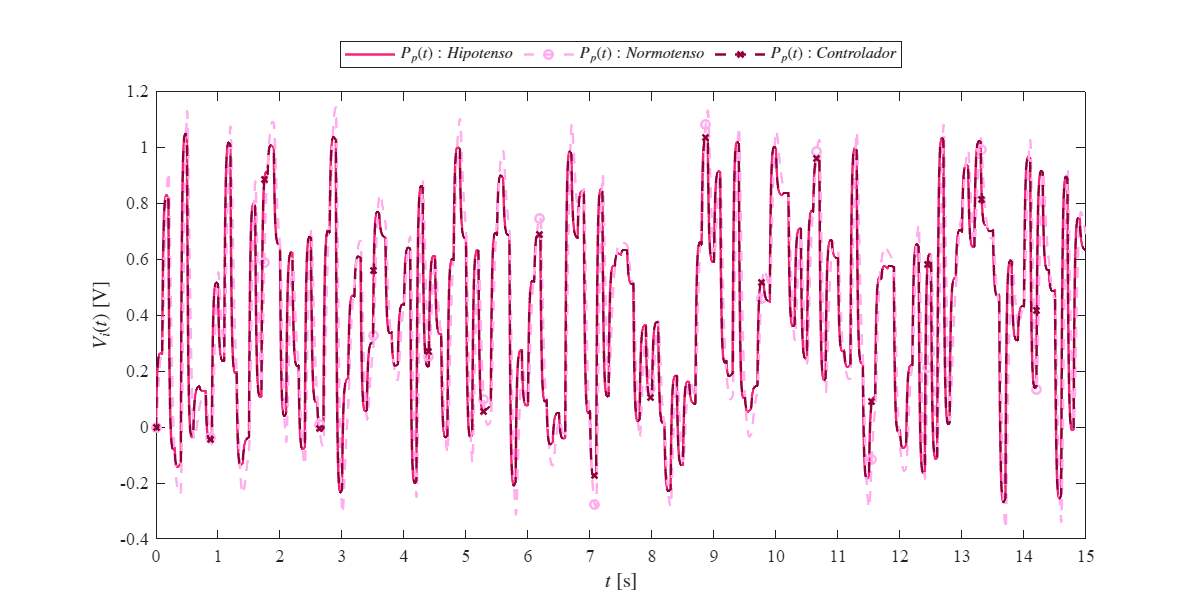

plotsignals(x.t,x.PpN,x.PpL,x.PIDL,'Hipotenso')

## Respuesta: Hipertenso

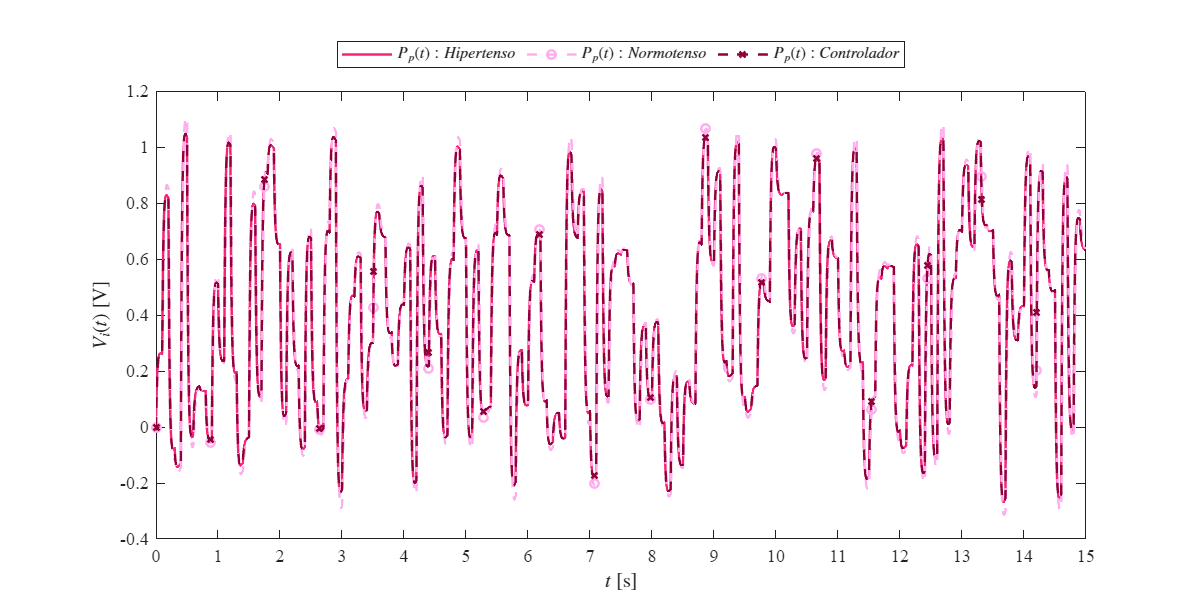

plotsignals(x.t,x.PpN,x.PpH,x.PIDH,'Hipertenso')

## Modelo de EDOs

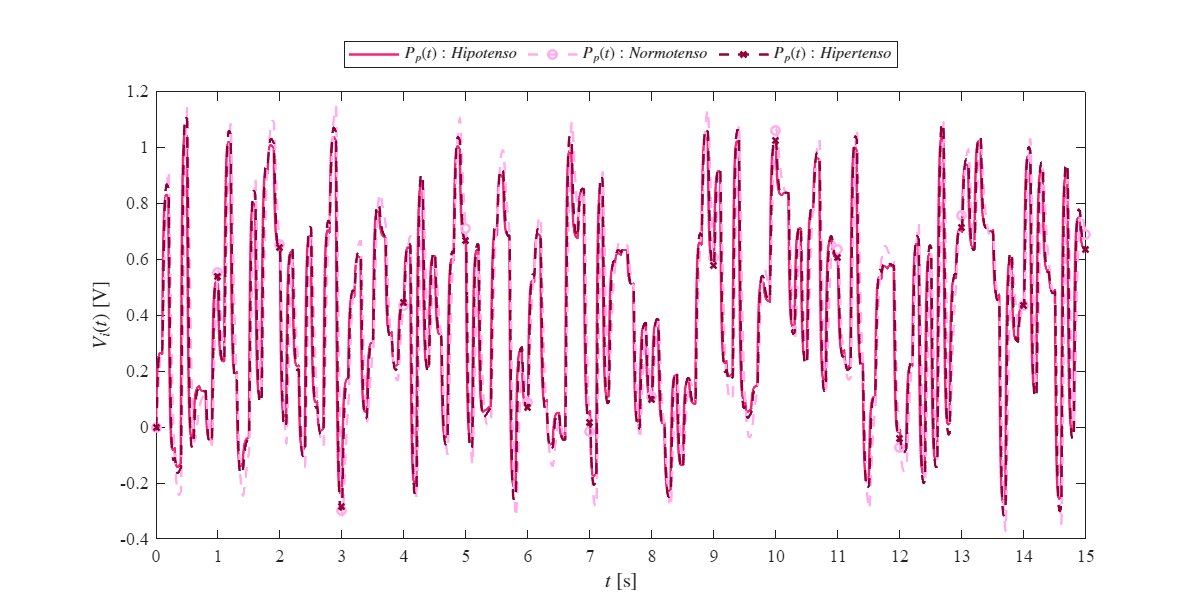

par_hipo = [0.010,0.001,1.000,3.500]; %[Z,L,R,C]
par_normo = [0.010,0.001,1.000,1.500];
par_hiper = [0.010,0.001,1.000,1.000]; 
PpN = cardio(par_normo,Pa,t);
PpL = cardio(par_hipo,PpN,t);
PpH = cardio(par_hiper,PpN,t);
plotsignals(t,PpN,PpL,PpH,'Individuos')



function Pp = cardio(par,Pa,t)
    Z = par(1); L = par(2); R = par(3); C = par(4);
    dt = t(2);
    n = round(t(end)/dt);
   

    FL = zeros(length(t),1); FL(1) = 0;
    Pp = zeros(length(t),1); Pp(1) = 0;

    for i = 1:n
        FL(i+1) = FL(i) + (-(1/L)*Pp(i) + (1/L)*Pa(i))*dt;
        Pp(i+1) = Pp(i) + ((1/C)*FL(i) - (1/(Z*C) + 1/(R*C))*Pp(i) +1/(Z*C)*Pa(i))*dt;
    end
end

## **Función: Respuestas de la simulación**

function plotsignals(t,PpN,PpL,PpH,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position', [1,1,10,5])
    set(gca, 'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = ([246, 36, 119])/255;
    clr2 = ([255, 173, 238])/255;
    clr3 = ([146, 0, 58])/255;
    order = [clr1;clr2;clr3]; colororder(order)

    plot(t,PpN,'-',t,PpL,'--o',t,PpH,'--x','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',...
        1:1e3:length(t));

  
    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$V_i(t)$ [V]', 'Interpreter','latex')

    xlim([0 15]); xticks(0:1:15)

    if signal == "Individuos"
        ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
        L = legend('$P_p(t): Hipotenso$','$P_p(t): Normotenso$','$P_p(t): Hipertenso$');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
   
    elseif signal == "Hipotenso"
        ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
       L = legend('$P_p(t):Hipotenso$','$P_p(t): Normotenso$','$P_p(t): Controlador$');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    
    elseif signal == "Hipertenso"
        ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
        L = legend('$P_p(t):Hipertenso$','$P_p(t):Normotenso$','$P_p(t): Controlador$');
    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    
    end

    exportgraphics(gcf,[signal, '_matlab.pdf'],'contenttype','vector')

end